# **Part 1**

Assume a random variable X has M symbols with the following distribution:


$$f_X \left(x\right)=\frac{1}{6};\textrm{for}\;x=\;1,2,3,4,5,\;\textrm{and}\;6\ldotp$$


### Mapping each symbol to a fixed-length code with the minimum number of bits needed to represent *M*

### symbols:

fprintf("Minimum number of bits needed to map each symbol of f(x) using a fixed-length code = %d bits ",ceil(log2(6)));

Minimum number of bits needed to map each symbol of f(x) using a fixed-length code = 3 bits 

FixedCode_X = ['100' '101' '110' '111' '010' '001'];
dispTable = ["100" "101" "110" "111" "010" "001"];
array2table(dispTable, "VariableNames",{'1' '2' '3' '4' '5' '6'}, "RowNames",{'Codeword'})

ans = 1×6 table
                  1        2        3        4        5        6  
                _____    _____    _____    _____    _____    _____

    Codeword    "100"    "101"    "110"    "111"    "010"    "001"


And of course, since each codeword has the same length, it would make sense that the average length of the codewords is *3.*

### Find a Huffman code and calculate its average code length.

X_symbols = (1:6); % Symbols vector
X_prob = [1/6 1/6 1/6 1/6 1/6 1/6]; % Symbol probability vector
[codeword_dict_x,average_length_x] = huffmandict(X_symbols,X_prob);
part1HuffmanTable = cell2table(codeword_dict_x);
part1HuffmanTable.Properties.VariableNames = {'Symbol', 'Codeword'};

disp(part1HuffmanTable)

    Symbol    Codeword 
    ______    _________

      1       {[  1 1]}
      2       {[  1 0]}
      3       {[0 0 1]}
      4       {[0 0 0]}
      5       {[0 1 1]}
      6       {[0 1 0]}




%Generate a binary Huffman code, displaying the average code length and the cell array containing the codeword dictionary.

%codeword_dict_x = cellfun(@num2str,codeword_dict_x(:,2),'UniformOutput',false);
%disp("Codeword of f(x)");
%huffTableX = cell2table(codeword_dict_x);
%disp((huffTableX));

%[dict,avglen] = huffmandict(X_symbols,X_prob)
%dict = cellfun(@num2str,dict(:,2),'UniformOutput',false)
%disp(dict)

H_X = 0;
 for i=1:length(X_prob)
 % Calculating the Entropy
 H_X = H_X + (-1*X_prob(i)*log2(X_prob(i)));
 end

 fprintf("Entropy of huffman code of f(x)=%.3f bits",H_X);

Entropy of huffman code of f(x)=2.585 bits

 fprintf("Average Length of huffman code of f(x)=%.3f ",average_length_x)

Average Length of huffman code of f(x)=2.667 

### Compare the average code lengths in parts 1) and 2) above to each other and to the Entropy of the random variable. 

Average Length of Huffman is less than  the code of a fixed-length.

The average length of Huffman is between the entropy  and entropy + 1

**Comment on your observations:**

Both codes are optimum codes as they are included in the bounds of the optomal code length (i.e. H <= L < H + 1)  but Huffman is better as it has average code length less than the other but due to equiprobable Huffman didn’t make that much difference than using normal code.  

**4) Using the attached .mat file of sample data from the random variable:**

***• *****Verify the probability mass function of the random variable.**

load(strcat(fileparts(matlab.desktop.editor.getActiveFilename),"\ELCN446_Project2_Spring2022.mat"));        %load the attached .mat file    (You don't need to load it again in Part II)
fprintf("The X variable is loaded and it has a length %d ",length(X));

The X variable is loaded and it has a length 960 

X_uniqueChars = unique(X); % String text has all characters, some are repeatedlenChar=length(uniqueChars);
disp(X_uniqueChars);

     1     2     3     4     5     6



%PMF%
f=zeros(1,length(X_uniqueChars));
for i=1:length(X_uniqueChars)
% Count the number of occurence of unique characters
f(i)=length(strfind(X,X_uniqueChars(i)));
end
p=zeros(1,length(X_uniqueChars));
PMF_X = [length(length(X_uniqueChars))]; % declare the Probability Mass Function with size of special chars
for i=1:length(X_uniqueChars)
% Probabilities for each unique character in the file
p(i)=f(i)/length(X);
PMF_X(i) = p(i); %PMF
end
disp("PMF of X")

PMF of X


array2table(PMF_X, "RowNames",{'PMF'}, "VariableNames",{'1' '2' '3' '4' '5' '6'})

ans = 1×6 table
              1          2          3          4          5          6   
           _______    _______    _______    _______    _______    _______

    PMF    0.16667    0.16667    0.16667    0.16667    0.16667    0.16667


%disp(transpose(PMF_X));

### Generate the source coded codewords for both the fixed-length code and the Huffman code.

%Generate the source coded code words using the fixed length code: 
%disp("Using the fixed Code:");
%disp("Encode the Codewords:")
Transmit_X_fixed =0;

for i=1:length(X)
    temp=0;
    for j=1:length(X_uniqueChars)
     if X(i)== X_uniqueChars(j)
         if i==1
             Transmit_X_fixed= FixedCode_X(j+temp*2:j+2+temp*2);
            % disp(Transmit_X_fixed)
         else
             Transmit_X_fixed = append(Transmit_X_fixed,FixedCode_X(j+temp*2:j+2+temp*2));  
             % disp(Transmit_X_fixed)
         end
         %disp("test")
     end
     temp = temp + 1;
    end
 end

 
 disp("The bits that are going to be transmitted using the Fixed code:"); 

The bits that are going to be transmitted using the Fixed code:


 disp(Transmit_X_fixed);

0011001010101000101000100101001001000010010010100011001001011100101101100010101101111101011001111101111100101111011011010101000101001011101101111010011110101101001010011011000101111111101011101000011101101111011110011001100101000101111101111100101111101010101101001001101010010101001100100101110101001010011101110010011000101001000101011000011100011011001001101101000100010011101011101010101001110100101000011110011110010101001110011111101001111101100100101100101100010011100101001011101011000100010101001110101010101000011000101000011111101000011101101111110101111111011001010101111110011111111101111100101010011111111011110101011111011111010101101110101011101000100011000011100101101111111001011011111011011011001111001111000011000101000101001011101001001001001101101011110100010010101000011011101100011001110101101001010011110101001000100011111010010011110100101110010100011101001110011101111100011101001010011001101101101111101111010101010011101011001011010101001111010011101011101001011100101001

 num_of_bits_X_fixed = length(Transmit_X_fixed);
 fprintf("The Total number of bits that are going to be transmitted using fixed code = %d", num_of_bits_X_fixed);

The Total number of bits that are going to be transmitted using fixed code = 2880


%Decode the data. Verify that the decoded symbols match the original symbols.

disp("Decode the Codewords back to symbols using the fixed code:")

Decode the Codewords back to symbols using the fixed code:


Recieve_X_fixed=[];
i=1;
indexX=1;
  while i<=length(Transmit_X_fixed)
      temp = 0;
     for j=1:length(X_uniqueChars)
     
          if indexX > length(X)
              break;
          end
          
          if Transmit_X_fixed(i:(i+2)) == FixedCode_X(j+temp*2:j+2+temp*2)
          
              Recieve_X_fixed(indexX) = X_uniqueChars(j) ;
              i = i+3;
              indexX=indexX+1;         
     
      
          end
          temp = temp + 1;
     end
  end
 disp(Recieve_X_fixed);

  Columns 1 through 22

     6     1     2     5     1     5     1     5     5     1     1     1     6     6     6     5     6     1     1     2     3     5

  Columns 23 through 44

     3     3     6     5     3     4     3     2     1     4     3     4     3     5     4     2     2     2     5     1     5     1

  Columns 45 through 66

     2     3     3     4     2     6     4     5     3     1     2     6     2     1     5     4     4     3     2     3     1     6

  Columns 67 through 88

     3     3     4     2     4     6     1     3     5     1     5     4     3     4     3     5     4     3     2     5     3     1

  Columns 89 through 110

     1     3     2     6     5     1     3     5     5     4     5     1     2     6     3     4     6     6     1     5     1     1

  Columns 111 through 132

     5     2     1     6     3     6     2     1     1     3     3     1     5     6     6     3     2     3     2     5     1     4

  Columns 133 through 154

     5     5     


if isequal(X,Recieve_X_fixed)
    disp("No losses were found when using the Fixed Code since the recieved bits of X are the same as the transmitted bits");
end

No losses were found when using the Fixed Code since the recieved bits of X are the same as the transmitted bits






%Generate the source coded code words using the Huffman code: 
disp("Using the Huffman code:");

Using the Huffman code:


[dict_sentX,avglen_sentX] = huffmandict(X_uniqueChars,PMF_X);   %X_unique: Symbols 
disp("Code Word of X that is Loaded from the .mat file:");

Code Word of X that is Loaded from the .mat file:


dict_sentX = cellfun(@num2str,dict_sentX(:,2),'UniformOutput',false);
disp(dict_sentX);

    {'1  1'   }
    {'1  0'   }
    {'0  0  1'}
    {'0  0  0'}
    {'0  1  1'}
    {'0  1  0'}





%disp("Test")
%disp((append(regexprep(cell2mat(dict_sentX(1)), '\s', '') , regexprep(cell2mat(dict_sentX(3)), '\s', ''))))
%disp(regexprep(cell2mat(dict_sentX(1)), '\s',''))
%disp(length(regexprep(cell2mat(dict_sentX(1)), '\s','')))
%zxc= regexprep(cell2mat(dict_sentX(1)), '\s','');
%disp(zxc)
%disp("test")
%disp(transpose(cell2mat(dict_sentX(1))))
%disp(regexprep(cell2mat(dict_sentX(3)), '\s', '') + regexprep(cell2mat(dict_sentX(2)), '\s', ''))

disp("Encode the Codewords:")

Encode the Codewords:


Transmit_X =0;
 for i=1:length(X)
    for j=1:length(X_uniqueChars)
     if X(i)== X_uniqueChars(j)
         if i==1
             Transmit_X= regexprep(cell2mat(dict_sentX(j)), '\s', '');
             %disp(Transmit_X)
         else
             Transmit_X = append(Transmit_X,regexprep(cell2mat(dict_sentX(j)), '\s', ''));            
         end
         %disp("test")
     end
    end
 end
 disp("The bits that are going to be transmitted using the huffman code:"); 

The bits that are going to be transmitted using the huffman code:


 disp(Transmit_X);

0101110011110111101101111111101001001001101011111000101100100101001100100000110110000010000010110001010100111101111100010010001001000001100111100101011011000000001100011101000100100010000010110010111101100000100000101100000110011001111100110010011110010110110000111110010001000010010110111111011101101000101010111100100111011010010001100011001111000011011110100000100000100111100001000000111000001001011011001011001010010001011111000110110110100111100001110011110101101111010000001110100010010000000110000001011100110000000100000000010000010111001000000010000011100001000010011001000011100011101101011010001011001000000111010000101010110001100011010110111101111100011111111100100110000011010010011110101000100101011000011001111001000001111110110100001001001000001101100001001101000111000010001000001010001111001011001001001000001000100111001000110111010011110001001000110001111000101111111101100000010100101011010111101001011001110110100000101100011000011100001001101011010001000011000011000011100101

 num_of_bits_X = length(Transmit_X);
 fprintf("The Total number of bits that are going to be transmitted = %d", num_of_bits_X);

The Total number of bits that are going to be transmitted = 2560

%Decode the data. Verify that the decoded symbols match the original symbols.
%sig = huffmandeco(double(Transmit_X),dict_sentX);

disp("Decode the Codewords back to symbols:")

Decode the Codewords back to symbols:


Recieve_X=[];
i=1;
indexX=1;
 while i<=length(Transmit_X)
     for j=3:length(dict_sentX)
     for k = 1:2
          if indexX > length(X)
              break;
          end
          
          if Transmit_X(i:(i+1)) == regexprep(cell2mat(dict_sentX(k)), '\s', '')
         
              Recieve_X(indexX) = X_uniqueChars(k) ;
              %disp(Recieve_X)  %for the test
              i = i+2;
              indexX=indexX+1;
    
          elseif  Transmit_X(i:(i+2)) == regexprep(cell2mat(dict_sentX(j)), '\s', '')
          
              Recieve_X(indexX) = X_uniqueChars(j) ;
              i = i+3;
              indexX=indexX+1;         
     
      end
      end
     end
  end
 disp(Recieve_X);

  Columns 1 through 22

     6     1     2     5     1     5     1     5     5     1     1     1     6     6     6     5     6     1     1     2     3     5

  Columns 23 through 44

     3     3     6     5     3     4     3     2     1     4     3     4     3     5     4     2     2     2     5     1     5     1

  Columns 45 through 66

     2     3     3     4     2     6     4     5     3     1     2     6     2     1     5     4     4     3     2     3     1     6

  Columns 67 through 88

     3     3     4     2     4     6     1     3     5     1     5     4     3     4     3     5     4     3     2     5     3     1

  Columns 89 through 110

     1     3     2     6     5     1     3     5     5     4     5     1     2     6     3     4     6     6     1     5     1     1

  Columns 111 through 132

     5     2     1     6     3     6     2     1     1     3     3     1     5     6     6     3     2     3     2     5     1     4

  Columns 133 through 154

     5     5     



if isequal(X,Recieve_X)
    disp("No losses were found when using the Huffman Code since the recieved bits of X are the same as the transmitted bits");
end

No losses were found when using the Huffman Code since the recieved bits of X are the same as the transmitted bits


### Compare the total number of bits to be transmitted in each case.

The Total number of bits to be transmitted using the naive code is greater than using the Huffman code since it's 2880 in naive code while it is 2560 in Huffman code 

so it is clear that the Huffman code is more efficient than the naive code. (i.e. send less number of bits)

### Decode the codewords back to symbols and check for any losses compared to the original data. 

No losses were found since the generated vector (The Recieved vector) is equal to the original vector.

# Part 2

### Map each symbol to a fixed-length code with the minimum number of bits needed to represent *M*

### symbols:

For F(y):

disp("F(y) :");

F(y) :


fprintf("Minimum number of bits needed to map each symbol of f(y) using a fixed-length code = %d bits ",ceil(log2(6)));

Minimum number of bits needed to map each symbol of f(y) using a fixed-length code = 3 bits 

fprintf("Average code length for a fixed-length code = %.2f",ceil(log2(6)));

Average code length for a fixed-length code = 3.00

FixedCode_Y = ['100' '101' '110' '111' '010' '001'];

So f(Y=1) will have the code: 100

     f(Y=2) will have the code: 101

     f(Y=3) will have the code: 110

     f(Y=4) will have the code: 111

     f(Y=5) will have the code: 010

     f(Y=6) will have the code: 001

Note: the code may be different every time

**2) Find a Huffman code and calculate its average code length.**

Y_symbols = (1:6); % Symbols vector
Y_prob = [(0.5)^1 (0.5)^2 (0.5)^3 (0.5)^4 (0.5)^5 (0.5)^5]; % Symbol probability vector
[codeword_dict_y,average_length_y] = huffmandict(Y_symbols,Y_prob);
disp("Size of the representation of the code with the minimum number of bits for each Y");

Size of the representation of the code with the minimum number of bits for each Y


display(['   symbol','  ','Size of codeword'])

   symbol  Size of codeword


disp(codeword_dict_y);

    {[1]}    {[        0]}
    {[2]}    {[      1 0]}
    {[3]}    {[    1 1 0]}
    {[4]}    {[  1 1 1 0]}
    {[5]}    {[1 1 1 1 1]}
    {[6]}    {[1 1 1 1 0]}




%Generate a binary Huffman code, displaying the average code length and the cell array containing the codeword dictionary.

codeword_dict_y = cellfun(@num2str,codeword_dict_y(:,2),'UniformOutput',false);
disp("Codeword of f(y)");

Codeword of f(y)


huffTableY = cell2table(codeword_dict_y);
disp((huffTableY));

     codeword_dict_y 
    _________________

    {'0'            }
    {'1  0'         }
    {'1  1  0'      }
    {'1  1  1  0'   }
    {'1  1  1  1  1'}
    {'1  1  1  1  0'}




%[dict,avglen] = huffmandict(X_symbols,X_prob)
%dict = cellfun(@num2str,dict(:,2),'UniformOutput',false)
%disp(dict)

H_Y = 0;
 for i=1:length(Y_prob)
 % Calculating the Entropy
 H_Y = H_Y + (-1*Y_prob(i)*log2(Y_prob(i)));
 end

 fprintf("Entropy of huffman code of f(y)=%.3f bits",H_Y);

Entropy of huffman code of f(y)=1.938 bits

 fprintf("Average Length of huffman code of f(y)=%.3f ",average_length_y);

Average Length of huffman code of f(y)=1.938 

**3) Compare the average code lengths in parts 1) and 2) above to each other and to the Entropy of the**

**random variable. **

Average Length of Huffman is less than  the code of a fixed-length.

The average length of Huffman code is equal to the entropy so it's most efficient coding compared to use than the naive code.

**Comment on your observations:**

The fixed length code isn’t an optimal code while Huffman is an optimal code and Huffman is better as it has average code length less than the other but due to equiprobable Huffman didn’t make that much difference than using normal code.  

**4) Using the attached .mat file of sample data from the random variable:**

***• *****Verify the probability mass function of the random variable.**

fprintf("The file .mat is already loaded from part I");

The file .mat is already loaded from part I

%load("ELCN446_Project2_Spring2022.mat");        %load the attached .mat file    (You don't need to load it again in Part II)
fprintf("The Y variable is loaded and it has a length %d ",length(Y));

The Y variable is loaded and it has a length 960 

Y_uniqueChars = unique(Y); % String text has all characters, some are repeatedlenChar=length(uniqueChars);
disp(Y_uniqueChars);

     1     2     3     4     5     6



%PMF%
f=zeros(1,length(Y_uniqueChars));
for i=1:length(Y_uniqueChars)
% Count the number of occurence of unique characters
f(i)=length(strfind(Y,Y_uniqueChars(i)));
end
p=zeros(1,length(Y_uniqueChars));
PMF_Y = [length(length(Y_uniqueChars))]; % declare the Probability Mass Function with size of special chars
for i=1:length(Y_uniqueChars)
% Probabilities for each unique character in the file
p(i)=f(i)/length(Y);
PMF_Y(i) = p(i); %PMF
end
disp("PMF of Y")

PMF of Y


disp(transpose(PMF_Y));

    0.5000
    0.2500
    0.1250
    0.0625
    0.0312
    0.0312



***• *****Generate the source coded codewords for both the fixed-length code and the Huffman code.**

%Generate the source coded code words using the fixed length code: 
disp("Using the fixed Code:");

Using the fixed Code:




disp("Encode the Codewords:")

Encode the Codewords:


Transmit_Y_fixed =0;

for i=1:length(Y)
    temp=0;
    for j=1:length(Y_uniqueChars)
     if Y(i)== Y_uniqueChars(j)
         if i==1
             Transmit_Y_fixed= FixedCode_Y(j+temp*2:j+2+temp*2);
            
         else
             Transmit_Y_fixed = append(Transmit_Y_fixed,FixedCode_Y(j+temp*2:j+2+temp*2));  
             
         end
         %disp("test")
     end
     temp = temp + 1;
    end
 end

 
 disp("The bits that are going to be transmitted using the Fixed code:"); 

The bits that are going to be transmitted using the Fixed code:


 disp(Transmit_Y_fixed);

1001001001001001001000101101101001111111111001001001011001011000011011111001001001101101101001011001001011001001011001001001011011001100101001001101010101001011011001101001000011001011001011001001001001011101001011101011001001101001001001001101011011001011011010011101001101001011001001001001101101001101001101001001011001001001010011111001001011001001001011000011011011001001101011001001001001001001011001101001011101001011011001111001111011001011001001011101000011101001011011101001011101010011001001101001001011101001001001001011011101001011011001100011001001001011001001001101011001011111011101011011011001011011101111101011010010101001001011011001001011001001011001001011001111001001001001001001011001011011001111111001001001011001011111011001001001010101101011101001001001000101011001011001001000100101001001011111001011001011001011001101001001010101101011001111111011001001111111001001011011011101011011001001011011001001101001001101001001011001011001001101101000011001001001001001101011011011

 num_of_bits_Y_fixed = length(Transmit_Y_fixed);
 fprintf("The Total number of bits that are going to be transmitted using fixed code = %d", num_of_bits_Y_fixed);

The Total number of bits that are going to be transmitted using fixed code = 2880


%Decode the data. Verify that the decoded symbols match the original symbols.

disp("Decode the Codewords back to symbols using the fixed code:")

Decode the Codewords back to symbols using the fixed code:


Recieve_Y_fixed=[];
i=1;
indexY=1;
  while i<=length(Transmit_Y_fixed)
      temp = 0;
     for j=1:length(Y_uniqueChars)
     
          if indexY > length(Y)
              break;
          end
          
          if Transmit_Y_fixed(i:(i+2)) == FixedCode_Y(j+temp*2:j+2+temp*2)
          
              Recieve_Y_fixed(indexY) = Y_uniqueChars(j) ;
              i = i+3;
              indexY=indexY+1;         
     
      
          end
          temp = temp + 1;
     end
  end
 disp(Recieve_Y_fixed);

  Columns 1 through 22

     1     1     1     1     1     1     1     5     3     3     1     4     4     4     1     1     1     2     1     2     1     6

  Columns 23 through 44

     2     4     1     1     1     3     3     3     1     2     1     1     2     1     1     2     1     1     1     2     2     1

  Columns 45 through 66

     3     5     1     1     3     2     5     1     2     2     1     3     1     1     6     1     2     1     2     1     1     1

  Columns 67 through 88

     1     2     3     1     2     3     2     1     1     3     1     1     1     1     3     2     2     1     2     2     2     6

  Columns 89 through 110

     3     1     3     1     2     1     1     1     1     3     3     1     3     1     3     1     1     2     1     1     1     2

  Columns 111 through 132

     6     4     1     1     2     1     1     1     2     1     6     2     2     1     1     3     2     1     1     1     1     1

  Columns 133 through 154

     1     2     


if isequal(Y,Recieve_Y_fixed)
    disp("No losses were found when using the Fixed Code since the recieved bits of Y are the same as the transmitted bits");
end

No losses were found when using the Fixed Code since the recieved bits of Y are the same as the transmitted bits






%Generate the source coded code words using the Huffman code: 
disp("Using the Huffman code:");

Using the Huffman code:


[dict_sentY,avglen_sentY] = huffmandict(Y_uniqueChars,PMF_Y);   %X_unique: Symbols 
disp("Code Word of Y that is Loaded from the .mat file:");

Code Word of Y that is Loaded from the .mat file:


dict_sentY = cellfun(@num2str,dict_sentY(:,2),'UniformOutput',false);
disp(dict_sentY);

    {'0'            }
    {'1  0'         }
    {'1  1  0'      }
    {'1  1  1  0'   }
    {'1  1  1  1  1'}
    {'1  1  1  1  0'}





%disp("Test")
%disp((append(regexprep(cell2mat(dict_sentX(1)), '\s', '') , regexprep(cell2mat(dict_sentX(3)), '\s', ''))))
%disp(regexprep(cell2mat(dict_sentX(1)), '\s',''))
%disp(length(regexprep(cell2mat(dict_sentX(1)), '\s','')))
%zxc= regexprep(cell2mat(dict_sentX(1)), '\s','');
%disp(zxc)
%disp("test")
%disp(transpose(cell2mat(dict_sentX(1))))
%disp(regexprep(cell2mat(dict_sentX(3)), '\s', '') + regexprep(cell2mat(dict_sentX(2)), '\s', ''))

disp("Encode the Codewords:")

Encode the Codewords:


Transmit_Y =0;
 for i=1:length(Y)
    for j=1:length(Y_uniqueChars)
     if Y(i)== Y_uniqueChars(j)
         if i==1
             Transmit_Y= regexprep(cell2mat(dict_sentY(j)), '\s', '');
             
         else
             Transmit_Y = append(Transmit_Y,regexprep(cell2mat(dict_sentY(j)), '\s', ''));            
         end
         %disp("test")
     end
    end
 end
 disp("The bits that are going to be transmitted using the huffman code:"); 

The bits that are going to be transmitted using the huffman code:


 disp(Transmit_Y);

0000000111111101100111011101110000100100111101011100001101101100100010001000010100110111110011010111110101001100011110010010000010110010110100011000001101010010101011110110011001000001101100110011000100001011110111000100001001111010100011010000000100110010110010100111001110100100010110011110110010101100101101011110001100010110000010101100101001101111000010000110100101110101101010100101011011101101010111101111100101000100010001001110000000100101001110111000010010111010000101111111010110000011111100100001111111111001011100100100100110001011111110100111011101000111011100010101011010100010100011000110001001000110110011110000001101010100111010010001001000001110110110101101011100010011101001001101001010011111011011111000000100000110100100001011011100111100111110011100110001000001011110011011000110010001000111001101000011110010111011110111001001011000111111111111010000110110111111110011000101100001010111011101101100001000101001010000101100100101010111101010011101000110001101100011010001010001

 num_of_bits_Y = length(Transmit_Y);
 fprintf("The Total number of bits that are going to be transmitted = %d", num_of_bits_Y);

The Total number of bits that are going to be transmitted = 1860



%Decode the data. Verify that the decoded symbols match the original symbols.
%sig = huffmandeco(double(Transmit_X),dict_sentX);

disp("Decode the Codewords back to symbols:")

Decode the Codewords back to symbols:


Recieve_Y=[];
i=1;
indexY=1;
 while i<=length(Transmit_Y)
     for j=5:length(dict_sentY)
     
          if indexY > length(Y)
              break;
          end
         if Transmit_Y(i) == regexprep(cell2mat(dict_sentY(1)), '\s', '')
             Recieve_Y(indexY) = Y_uniqueChars(1) ;
              %disp(Recieve_Y)  %for the test
              i = i+1;
              indexY=indexY+1;
              break;
             
        elseif Transmit_Y(i:(i+1)) == regexprep(cell2mat(dict_sentY(2)), '\s', '')
         
              Recieve_Y(indexY) = Y_uniqueChars(2) ;
              %disp(Recieve_Y)  %for the test
              i = i+2;
              indexY=indexY+1;
              break;
              
        elseif Transmit_Y(i:(i+2)) == regexprep(cell2mat(dict_sentY(3)), '\s', '')
                  
         
              Recieve_Y(indexY) = Y_uniqueChars(3) ;
              %disp(Recieve_Y)  %for the test
              i = i+3;
              indexY=indexY+1;
              break;
              
        elseif Transmit_Y(i:(i+3)) == regexprep(cell2mat(dict_sentY(4)), '\s', '')
                  
         
              Recieve_Y(indexY) = Y_uniqueChars(4) ;
              %disp(Recieve_Y)  %for the test
              i = i+4;
              indexY=indexY+1;
              break;
    
          elseif  Transmit_Y(i:(i+4)) == regexprep(cell2mat(dict_sentY(j)), '\s', '')
          
              Recieve_Y(indexY) = Y_uniqueChars(j) ;
             % disp(Recieve_Y)  %for the test
              i = i+5;
              indexY=indexY+1;         
              break;
      
      end
     end
  end
 disp(Recieve_Y);

  Columns 1 through 22

     1     1     1     1     1     1     1     5     3     3     1     4     4     4     1     1     1     2     1     2     1     6

  Columns 23 through 44

     2     4     1     1     1     3     3     3     1     2     1     1     2     1     1     2     1     1     1     2     2     1

  Columns 45 through 66

     3     5     1     1     3     2     5     1     2     2     1     3     1     1     6     1     2     1     2     1     1     1

  Columns 67 through 88

     1     2     3     1     2     3     2     1     1     3     1     1     1     1     3     2     2     1     2     2     2     6

  Columns 89 through 110

     3     1     3     1     2     1     1     1     1     3     3     1     3     1     3     1     1     2     1     1     1     2

  Columns 111 through 132

     6     4     1     1     2     1     1     1     2     1     6     2     2     1     1     3     2     1     1     1     1     1

  Columns 133 through 154

     1     2     



if isequal(Y,Recieve_Y)
    disp("No losses were found when using the Huffman Code since the recieved bits of Y are the same as the transmitted bits");
end

No losses were found when using the Huffman Code since the recieved bits of Y are the same as the transmitted bits


**Compare the total number of bits to be transmitted in each case.**

The Total number of bits to be transmitted using the naive code is greater than using the Huffman code since it's 2880 in naive code while it is 1860 in Huffman code 

so it is clear that the Huffman code is more efficient than the naive code. (i.e. send less number of bits)

***• *****Decode the codewords back to symbols and check for any losses compared to the original data. **

No losses were found since the generated vector (The Recieved) is equal to the original vector

**For F(Z):**

**1) Map each symbol to a fixed-length code with the minimum number of bits needed to represent *****M***

**symbols.**

disp("F(z) :");

F(z) :


fprintf("Minimum number of bits needed to map each symbol of f(z) using a fixed-length code = %d bits ",ceil(log2(6)));

Minimum number of bits needed to map each symbol of f(z) using a fixed-length code = 3 bits 

fprintf("Average code length for a fixed-length code = %.2f",ceil(log2(6)));

Average code length for a fixed-length code = 3.00

FixedCode_Z = ['100' '101' '110' '111' '010' '001'];

So f(Z=1) will have the code: 100

     f(Z=2) will have the code: 101

     f(Z=3) will have the code: 110

     f(Z=4) will have the code: 111

     f(Z=5) will have the code: 010

     f(Z=6) will have the code: 001

Note: the code may be different every time

**2) Find a Huffman code and calculate its average code length.**

Z_symbols = (1:6); % Symbols vector
Z_prob = [0.05 0.10 0.30 0.25 0.15 0.15]; % Symbol probability vector
[codeword_dict_z,average_length_z] = huffmandict(Z_symbols,Z_prob);
disp("Size of the representation of the code with the minimum number of bits for each Z");

Size of the representation of the code with the minimum number of bits for each Z


display(['   symbol','  ','Size of codeword'])

   symbol  Size of codeword


disp(codeword_dict_z);

    {[1]}    {[1 1 1]}
    {[2]}    {[1 1 0]}
    {[3]}    {[  0 0]}
    {[4]}    {[  1 0]}
    {[5]}    {[0 1 1]}
    {[6]}    {[0 1 0]}




%Generate a binary Huffman code, displaying the average code length and the cell array containing the codeword dictionary.

codeword_dict_z = cellfun(@num2str,codeword_dict_z(:,2),'UniformOutput',false);
disp("Codeword of f(z)");

Codeword of f(z)


huffTableZ = cell2table(codeword_dict_z);
disp((huffTableZ));

    codeword_dict_z
    _______________

      {'1  1  1'}  
      {'1  1  0'}  
      {'0  0'   }  
      {'1  0'   }  
      {'0  1  1'}  
      {'0  1  0'}  




%[dict,avglen] = huffmandict(X_symbols,X_prob)
%dict = cellfun(@num2str,dict(:,2),'UniformOutput',false)
%disp(dict)

H_Z = 0;
 for i=1:length(Z_prob)
 % Calculating the Entropy
 H_Z = H_Z + (-1*Z_prob(i)*log2(Z_prob(i)));
 end

 fprintf("Entropy of huffman code of f(z)=%.3f bits",H_Z);

Entropy of huffman code of f(z)=2.390 bits

 fprintf("Average Length of huffman code of f(z)=%.3f ",average_length_z);

Average Length of huffman code of f(z)=2.450 

**3) Compare the average code lengths in parts 1) and 2) above to each other and to the Entropy of the**

**random variable. **

Average Length of Huffman is less than  the code of a fixed-length so Huffman is more efficient.

The average length for Huffman code is between the entropy  and entropy + 1 so it's more optimum.

**Comment on your observations:**

Both codes are optimum codes as they are included in the bounds of the optomal code length (i.e. H <= L < H + 1)  but Huffman is better as it has average code length less than the other but due to equiprobable Huffman didn’t make that much difference than using normal code.  

**4) Using the attached .mat file of sample data from the random variable:**

***• *****Verify the probability mass function of the random variable.**

fprintf("The file .mat is already loaded from part I");

The file .mat is already loaded from part I

%load("ELCN446_Project2_Spring2022.mat");        %load the attached .mat file    (You don't need to load it again in Part II)
fprintf("The Z variable is loaded and it has a length %d ",length(Z));

The Z variable is loaded and it has a length 960 

Z_uniqueChars = unique(Z); % String text has all characters, some are repeatedlenChar=length(uniqueChars);
disp(Z_uniqueChars);

     1     2     3     4     5     6



%PMF%
f=zeros(1,length(Z_uniqueChars));
for i=1:length(Z_uniqueChars)
% Count the number of occurence of unique characters
f(i)=length(strfind(Z,Z_uniqueChars(i)));
end
p=zeros(1,length(Z_uniqueChars));
PMF_Z = [length(length(Z_uniqueChars))]; % declare the Probability Mass Function with size of special chars
for i=1:length(Z_uniqueChars)
% Probabilities for each unique character in the file
p(i)=f(i)/length(Z);
PMF_Z(i) = p(i); %PMF
end
disp("PMF of Z")

PMF of Z


disp(transpose(PMF_Z));

    0.0500
    0.1000
    0.3000
    0.2500
    0.1500
    0.1500



***• *****Generate the source coded codewords for both the fixed-length code and the Huffman code.**

    
%Generate the source coded code words using the fixed length code: 
disp("Using the fixed Code:");

Using the fixed Code:




disp("Encode the Codewords:")

Encode the Codewords:


Transmit_Z_fixed =0;

for i=1:length(Z)
    temp=0;
    for j=1:length(Z_uniqueChars)
     if Z(i)== Z_uniqueChars(j)
         if i==1
             Transmit_Z_fixed= FixedCode_Z(j+temp*2:j+2+temp*2);
            % disp(Transmit_X_fixed)
         else
             Transmit_Z_fixed = append(Transmit_Z_fixed,FixedCode_Z(j+temp*2:j+2+temp*2));  
             % disp(Transmit_X_fixed)
         end
         %disp("test")
     end
     temp = temp + 1;
    end
 end

 
 disp("The bits that are going to be transmitted using the Fixed code:"); 

The bits that are going to be transmitted using the Fixed code:


 disp(Transmit_Z_fixed);

1111101111111111110010011100011111001011110011101100011111100101100101010100011101011010010011111110010100101011100011111010101101101001101101101101101101001101110101110101101010010011111110101101101111110101101111111111110011001101000100101100101101111101111101110100010101001010011111100100011001001111101000101101100101101101111111101100010101101100011111101011111111111111001100101101111111110101110011100101111011111110011100011110101110011101100011111110100011110011110011111101011100100011101011111011111011110100101101111100100010101111100100010101101110101010011101101110101011100101101101100101101101100101101001111111101111111011101110011101101111011100100011111010010101101111101101110011100100101101101010101111001111100011100011101101101100011000101100011001101110011110101101101100101001111111011100101011100101110011101100101101100100100010011111111101110011111101100101110101110011110010011100011011010011101001100011110100101111110011101111101110100101101011111101010100011010011101

 num_of_bits_Z_fixed = length(Transmit_Z_fixed);
 fprintf("The Total number of bits that are going to be transmitted using fixed code = %d", num_of_bits_Z_fixed);

The Total number of bits that are going to be transmitted using fixed code = 2880


%Decode the data. Verify that the decoded symbols match the original symbols.

disp("Decode the Codewords back to symbols using the fixed code:")

Decode the Codewords back to symbols using the fixed code:


Recieve_Z_fixed=[];
i=1;
indexZ=1;
  while i<=length(Transmit_Z_fixed)
      temp = 0;
     for j=1:length(Z_uniqueChars)
     
          if indexZ > length(Z)
              break;
          end
          
          if Transmit_Z_fixed(i:(i+2)) == FixedCode_Z(j+temp*2:j+2+temp*2)
          
              Recieve_Z_fixed(indexZ) = Z_uniqueChars(j) ;
              i = i+3;
              indexZ=indexZ+1;         
     
      
          end
          temp = temp + 1;
     end
  end
 disp(Recieve_Z_fixed);

  Columns 1 through 22

     4     3     4     4     4     4     6     6     3     6     4     1     2     4     6     3     3     6     4     3     5     3

  Columns 23 through 44

     5     2     5     6     3     2     2     6     6     4     4     6     5     5     2     3     6     4     2     5     3     3

  Columns 45 through 66

     1     3     3     3     3     3     3     1     3     4     5     4     5     3     2     6     6     4     4     5     3     3

  Columns 67 through 88

     4     4     5     3     4     4     4     4     6     1     3     1     5     5     3     5     3     4     3     4     3     4

  Columns 89 through 110

     5     6     5     1     2     6     4     3     5     6     1     1     4     3     1     5     3     3     5     3     3     4

  Columns 111 through 132

     4     3     3     6     5     3     3     6     4     3     2     4     4     4     4     1     3     5     3     4     4     4

  Columns 133 through 154

     5     4     




if isequal(Z,Recieve_Z_fixed)
    disp("No losses were found when using the Fixed Code since the recieved bits of Z are the same as the transmitted bits");
end

No losses were found when using the Fixed Code since the recieved bits of Z are the same as the transmitted bits



%Generate the source coded code words using the Huffman code: 
disp("Using the Huffman code:");

Using the Huffman code:


[dict_sentZ,avglen_sentZ] = huffmandict(Z_uniqueChars,PMF_Z);   %X_unique: Symbols 
disp("Code Word of Z that is Loaded from the .mat file:");

Code Word of Z that is Loaded from the .mat file:


dict_sentZ = cellfun(@num2str,dict_sentZ(:,2),'UniformOutput',false);
disp(dict_sentZ);

    {'1  1  1'}
    {'1  1  0'}
    {'0  0'   }
    {'1  0'   }
    {'0  1  1'}
    {'0  1  0'}





%disp("Test")
%disp((append(regexprep(cell2mat(dict_sentX(1)), '\s', '') , regexprep(cell2mat(dict_sentX(3)), '\s', ''))))
%disp(regexprep(cell2mat(dict_sentX(1)), '\s',''))
%disp(length(regexprep(cell2mat(dict_sentX(1)), '\s','')))
%zxc= regexprep(cell2mat(dict_sentX(1)), '\s','');
%disp(zxc)
%disp("test")
%disp(transpose(cell2mat(dict_sentX(1))))
%disp(regexprep(cell2mat(dict_sentX(3)), '\s', '') + regexprep(cell2mat(dict_sentX(2)), '\s', ''))

disp("Encode the Codewords:")

Encode the Codewords:


Transmit_Z =0;
 for i=1:length(Z)
    for j=1:length(Z_uniqueChars)
     if Z(i)== Z_uniqueChars(j)
         if i==1
             Transmit_Z= regexprep(cell2mat(dict_sentZ(j)), '\s', '');
             %disp(Transmit_X)
         else
             Transmit_Z = append(Transmit_Z,regexprep(cell2mat(dict_sentZ(j)), '\s', ''));            
         end
         %disp("test")
     end
    end
 end
 disp("The bits that are going to be transmitted using the huffman code:"); 

The bits that are going to be transmitted using the huffman code:


 disp(Transmit_Z);

1000101010100100100001010111110100100000010100001100011110011010001101100100101010010011011110000101011001100001110000000000001110010011100110011001001010100110000101001100101010100101110011101101100011001000100010011010011111110010100001101011111110001110110000011000010100000010011000001010001101010101011100011001010100111001000011101101010010000101001110010000001010100110101001010010100011000011010001101011010110100110110010000110100111000011010011001001111001000001001111000011000000011000000011001111010001010110001001000001011000011010101100100110010000010010000110110000110011101111000010000100000000001011101100010111001001010011000000011111101011000011110000111001000000110000011011010010101000100101000000111001110010100100100001011011001000111000101001101110100100010001001101100110100011001101011001000110101000011100001100100110011000111010000110100010100100101101111011010111000001000011101010000111001110000101101100100101001001010000100100100111000100011100100001010010101011000110

 num_of_bits_Z = length(Transmit_Z);
 fprintf("The Total number of bits that are going to be transmitted = %d", num_of_bits_Z);

The Total number of bits that are going to be transmitted = 2352



%Decode the data. Verify that the decoded symbols match the original symbols.
%sig = huffmandeco(double(Transmit_X),dict_sentX);

disp("Decode the Codewords back to symbols:")

Decode the Codewords back to symbols:


Recieve_Z=[];
i=1;
indexZ=1;
 while i<=length(Transmit_Z)
     for j=5:length(dict_sentZ)
     for l=3:4    
     for k = 1:2
          if indexZ > length(Z)
              break;
          end
          
          if Transmit_Z(i:(i+1)) == regexprep(cell2mat(dict_sentZ(l)), '\s', '')
         
              Recieve_Z(indexZ) = Z_uniqueChars(l) ;
              %disp(Recieve_X)  %for the test
              i = i+2;
              indexZ=indexZ+1;
    
          elseif  Transmit_Z(i:(i+2)) == regexprep(cell2mat(dict_sentZ(j)), '\s', '')
          
              Recieve_Z(indexZ) = Z_uniqueChars(j) ;
              i = i+3;
              indexZ=indexZ+1;    
              
          elseif  Transmit_Z(i:(i+2)) == regexprep(cell2mat(dict_sentZ(k)), '\s', '')
          
              Recieve_Z(indexZ) = Z_uniqueChars(k) ;
              i = i+3;
              indexZ=indexZ+1; 
     
      end
      end
     end
     end
 end
 disp(Recieve_Z);

  Columns 1 through 22

     4     3     4     4     4     4     6     6     3     6     4     1     2     4     6     3     3     6     4     3     5     3

  Columns 23 through 44

     5     2     5     6     3     2     2     6     6     4     4     6     5     5     2     3     6     4     2     5     3     3

  Columns 45 through 66

     1     3     3     3     3     3     3     1     3     4     5     4     5     3     2     6     6     4     4     5     3     3

  Columns 67 through 88

     4     4     5     3     4     4     4     4     6     1     3     1     5     5     3     5     3     4     3     4     3     4

  Columns 89 through 110

     5     6     5     1     2     6     4     3     5     6     1     1     4     3     1     5     3     3     5     3     3     4

  Columns 111 through 132

     4     3     3     6     5     3     3     6     4     3     2     4     4     4     4     1     3     5     3     4     4     4

  Columns 133 through 154

     5     4     


 
 if isequal(Z,Recieve_Z)
     disp("No losses were found when using the Huffman Code since the recieved bits of Z are the same as the transmitted bits");
 end

No losses were found when using the Huffman Code since the recieved bits of Z are the same as the transmitted bits


**Compare the total number of bits to be transmitted in each case.**

The Total number of bits to be transmitted using the naive code is greater than using the Huffman code since it's 2880 in naive code while it is 2352 in Huffman code 

so it is clear that the Huffman code is more efficient than the naive code. (i.e. send less number of bits)

***• *****Decode the codewords back to symbols and check for any losses compared to the original data. **

No losses were found since the generated vector (The recieved) is equal to the original vector.

## **Comment on your observations of Part II compared to Part I  **

Huffman is always better than the fixed code as it generates an optimum code and efficient code compared to the fixed.

In addition, Huffman generates least number of codewords to the highest probability so decreases the average code length

# Part 3

In this part, we are required to compress a text file using *Huffman* codes.

First, We need to acquire the text. You can select a text file by pressing the browse button:

 
textFromFile = false;
[file , path] = uigetfile ('*.txt');

if(~file)
    disp('No file was selected.');
else
    disp(strcat("Selected file: ", file));
    originalText = fileread (strcat(path,file));
    textFromFile = true;
end

Selected file: s p a c e.txt


Selected text:

disp(originalText);

s p a c e


Our file should consist of these characters only:

charList = char(strcat(char(65:90),char(97:122), char(49:57), ",. "))

charList = 'ABCDEFGHIJKLMNOPQRSTUVWXYZabcdefghijklmnopqrstuvwxyz123456789,. '

We now extract the character data from the file and find its *Probability Mass Function, *after removing all invalid characters:

originalText(~ismember(originalText, charList)) = '';
sortedText = sort(originalText);
[labels, charPMF] = PMF(sortedText);
pmfTable = table(transpose(labels), transpose(charPMF), 'VariableNames', {'Character', 'Probability'});
disp(pmfTable)

    Character    Probability
    _________    ___________

                   0.44444  
        a          0.11111  
        c          0.11111  
        e          0.11111  
        p          0.11111  
        s          0.11111  



## Huffman Encoding

We can now use the built in function to generate a Huffman code for our file:

% The huffmandict function can't deal with the symbols as chars. We need to
% cast them into doubles.


symbols = double(labels);
dict = huffmandict(symbols, charPMF);
huffTable = cell2table(dict);
huffTable.Properties.VariableNames = {'Character', 'Codeword'};
huffTable.Character = char(huffTable.Character);

disp(huffTable)

    Character     Codeword  
    _________    ___________

                 {[      1]}
        a        {[  0 1 1]}
        c        {[  0 1 0]}
        e        {[0 0 0 1]}
        p        {[0 0 0 0]}
        s        {[  0 0 1]}



Now, we are ready to encode our text file:

encoded = huffmanenco(originalText, dict);
huffman = num2str(encoded);
huffman = strrep(huffman,' ','');
ascii = dec2bin(originalText);
ascii = reshape(ascii',1,[]);

codeTable = cell2table({ascii; huffman});
codeTable.Properties.VariableNames = {'Encoded File'};
codeTable.Properties.RowNames = {'ASCII', 'Huffman'};
disp(codeTable)

                                          Encoded File                            
               ___________________________________________________________________

    ASCII      {'111001101000001110000010000011000010100000110001101000001100101'}
    Huffman    {'001100001011101010001'                                          }



We know find the compression ratio:

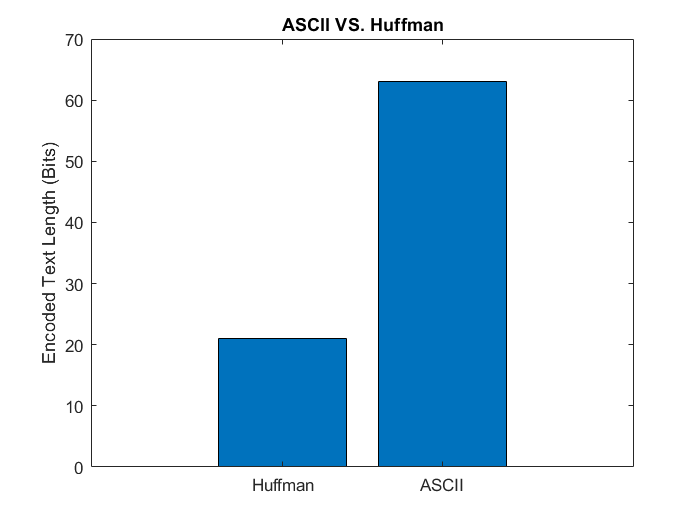

huffLen = length(huffman);
asciiLen = length(ascii);
lenArr = [huffLen asciiLen];
gra = bar(lenArr);
xticklabels({'Huffman', 'ASCII'});
title('ASCII VS. Huffman');
ylabel('Encoded Text Length (Bits)');

We can now calculate the compression ratio by applying the formula:


$$\frac{\mathrm{Length}\;\mathrm{of}\;\mathrm{Huffman}\;\mathrm{code}}{\mathrm{Length}\;\mathrm{of}\;\mathrm{ASCII}\;\mathrm{code}}\times 100%$$


% compRatio = ((asciiLen - huffLen)/asciiLen) * 100;
% fprintf("η = %f %%", compRatio)
compRatio = (huffLen / asciiLen) * 100;
fprintf("η = %f %%", compRatio)

η = 33.333333 %

## Decoding

We now decode both the ASCII and the Huffman files to check for errors. We expect none due to the one-to-one mapping in both ASCII and Huffman:

decodedHuff = char(huffmandeco(encoded, dict));
decodedASCII = zeros(1, asciiLen);

for i = 1:7:asciiLen-6
    % We need to decode each 7 bits into a single character
    
    letterBits = extractBetween(ascii, i, i+6);
    
    letter = char(bin2dec(letterBits));
    if letter == ' '
        decodedASCII = strcat(decodedASCII," ");
    else
        decodedASCII = strcat(decodedASCII, letter);
    end
    
end


decodeTable = cell2table({decodedASCII; decodedHuff});
decodeTable.Properties.VariableNames = {'Decoded File'};
decodeTable.Properties.RowNames = {'ASCII', 'Huffman'};
disp(decodeTable);

               Decoded File
               ____________

    ASCII      "s p a c e" 
    Huffman    "s p a c e" 




% And now, we compare the decoded text with the original text:

if(strcmp(decodedHuff, originalText))
    disp("Huffman codes are error free as expected.")
end

Huffman codes are error free as expected.



if(strcmp(decodedASCII, originalText))
    disp("ASCII codes are error free as expected.")
end

ASCII codes are error free as expected.


We now output the Huffman decoded file for further inspection:

 
fid = fopen(strcat(path,"huffman.txt"),'w+');
fprintf(fid, decodedHuff);
fclose(fid);

## Comments

- Huffman coding is a lossless coding method, which by definition means it's error free.

- ASCII codes are made for computers to represent text, not for compression. We have 64 characters in our character list, which means we need only $\log_2 \left(64\right)=6\;\textrm{Bits}$ to represent each charachter, not $7\;\textrm{Bits}$.

## Functions

function  [uniqueChars, pmfCharArr] = PMF(text)
            % Returns the probability of each charachter in an array
            
            textLen = length(text);
            uniqueChars = unique(text);
            uniques = length(uniqueChars);
            pmfCharArr = zeros(1, uniques);
            
            for idx = 1:uniques
                pmfCharArr(idx) = sum(text == uniqueChars(idx)) / textLen ;
            end
 end
